# ** Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                       % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Starts     = {9};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.Static = [20 21 23 24] ;
Deci.DT.Displace.Markers = {[31 32] [51 52]};
Deci.DT.Displace.Duration =2;
Deci.DT.Displace.Num = 1;
%Displace will add a new marker of .Num*1000 + displaced trial marker

Deci.DT.Block.Markers   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [1 50];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];   
Deci.Art.AddComponents =  true;

## 4. Analysis

## 5. Plotting

## ** 6. Run**

Running Deci for 20 subjects
 
----------------------
 
Plotting TotalPower
Loading Plottor for Subject #1: Instru_EEG_002INT
Loading Plottor for Subject #2: Instru_EEG_003INT
Loading Plottor for Subject #3: Instru_EEG_006INT
Loading Plottor for Subject #4: Instru_EEG_007INT
Loading Plottor for Subject #5: Instru_EEG_008INT
Loading Plottor for Subject #6: Instru_EEG_009INT
Loading Plottor for Subject #7: Instru_EEG_010INT
Loading Plottor for Subject #8: Instru_EEG_011
Loading Plottor for Subject #9: Instru_EEG_011INT
Loading Plottor for Subject #10: Instru_EEG_014
Loading Plottor for Subject #11: Instru_EEG_017
Loading Plottor for Subject #12: Instru_EEG_018
Loading Plottor for Subject #13: Instru_EEG_019
Loading Plottor for Subject #14: Instru_EEG_032
Loading Plottor for Subject #15: Instru_EEG_044
Loading Plottor for Subject #16: Instru_EEG_059
Loading Plottor for Subject #17: Instru_EEG_063
Loading Plottor for Subject #18: Instru_EEG_071
Loading Plottor for Subject #19: Instru_EEG_0

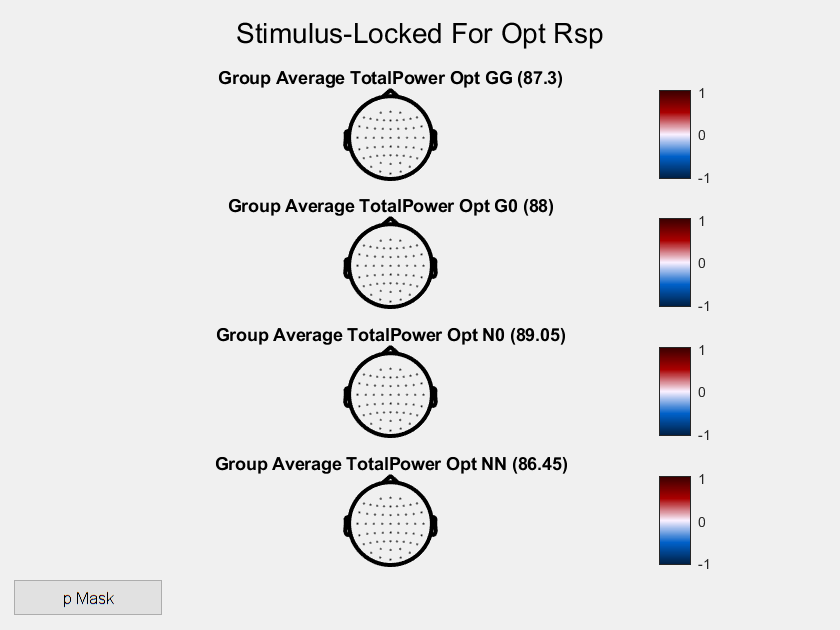

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


%LockTypes = {'Instru_StimLocked','Instru_StimLocked_Hemi', 'Instru_RspLocked', 'Instru_RspLocked_Hemi', 'Instru_FdbLocked','Instru_FdbLocked_Hemi','Instru_All','Instru_FdbLockedAll'};
%LockTypes = {'Instru_StimLocked_Hemi','Instru_RspLocked_Hemi','Instru_FdbLocked_Hemi'};
%LockTypes = {'Instru_StimLocked','Instru_StimLocked_Hemi'};
%LockTypes = {'Instru_All'};
LockTypes = {'Instru_StimLocked_BBcorr'};

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

if Deci.Step == 4
    
    Deci = Checkor(Deci);
    for AnalysisLocks = LockTypes
        Deci_Wavelet;
        eval(AnalysisLocks{1})
        
        
        
        Deci.SubjectList        = 'all';  
        
        Deci.Analysis.ERP.do  = false;
        Deci.Analysis.Freq.do  = false;
        Deci.Analysis.Extra.do  = true;
        
        Deci_Backend(Deci);
        Deci = rmfield(Deci,'Analysis');
    end
else
    
    Instru_RspLocked_Hemi;
    Deci.Plot.BslRef = 'Response Onset';
    Deci.Plot.Lock = 'Response Onset';
    
    Deci.Plot.GrandAverage = true;
    
    Deci.Plot.Freq.Topo.do    =true;
    Deci.Plot.Freq.Topo.Foi     = [13 30];                   % Frequency of Interest
    Deci.Plot.Freq.Topo.Toi     = [1 1.5];                   % Time of Interest
    Deci.Plot.Freq.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Freq.Square.do  =false;
    Deci.Plot.Freq.Square.Foi     = [3 inf];                 % Frequency of Interest
    Deci.Plot.Freq.Square.Toi     = [];                   % Time of Interest
    Deci.Plot.Freq.Square.Channel = ['Reinhart-All'];                % Channel of Interest
    
    Deci.Plot.Freq.Wire.do    =false;
    Deci.Plot.Freq.Wire.Foi     = [3 8];           % Frequency of Interest
    Deci.Plot.Freq.Wire.Toi     = [];                   % Time of Interest
    Deci.Plot.Freq.Wire.Channel = [{'P8'}];              % Channel of Interest
    
    Deci.Plot.Freq.Bar.do    =false;
    Deci.Plot.Freq.Bar.Foi     =  [3 8];                 % Frequency of Interest
    Deci.Plot.Freq.Bar.Toi     = [0 .5];                   % Time of Interest
    Deci.Plot.Freq.Bar.Channel =  [{'P8'}];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower'; 
    
    if  strcmpi(Deci.Plot.BslRef, 'Response Onset')
        Deci.Plot.Freq.Bsl     = [-.5 -.3];
    else
        Deci.Plot.Freq.Bsl     = [-.5 0];
    end
    
    if  Deci.Plot.Freq.Square.do  
    Omnibus = true;
    
    Deci.Plot.Stat.do = true;
    if Omnibus == true
        Deci.Plot.Stat.Comp = 'Bsl';
        Deci.Plot.Stat.alpha = .01;
        Deci.Plot.Stat.correctm = 'fdr';
        Deci.Plot.Freq.BslType = 'db'
        Deci.Plot.Stat.FPlots =  false;
    end
    Deci.Plot.Stat.FPlots =  false;
    end
    
    if Deci.Plot.Freq.Topo.do
    Perma = true;
    
    if Perma == true
        Deci.Plot.Stat.Type = 'Randomize Permutation';
        Deci.Plot.Stat.alpha = .05;
        Deci.Plot.Stat.FPlots =  false;
    end
    end

Deci_Backend(Deci);
end